magcal_smooth=smoothdata(imucal,'movmedian',10);
plot(magcal_smooth(:,1),magcal_smooth(:,2))

x=magcal_smooth;
p0=[0.005 0.005 0.005 0.005 0.005 0.005];
warning off
F=@(p,x)p(1)*x(:,1).^2+p(2)*x(:,1).*x(:,2)+p(3)*x(:,2).^2+p(4)*x(:,1)+p(5)*x(:,2)+p(6);
% 拟合系数，最小二乘方法
p=nlinfit(x,zeros(size(x,1),1),F,p0);
p(1)

ans = 5.7933e-32

p(2)

ans = 7.6938e-34

p(3)

ans = 5.9575e-32

p(4)

ans = -2.9549e-29

p(5)

ans = -9.3740e-30

p(6)

ans = 1.0204e-27



A=p(1)/p(6);
B=p(2)/p(6);
C=p(3)/p(6);
D=p(4)/p(6);
E=p(5)/p(6);


%%椭圆中心
X_center = (B*E-2*C*D)/(4*A*C - B^2);
Y_center = (B*D-2*A*E)/(4*A*C - B^2);
fprintf(' X_center=%g, Y_center=%g\n',X_center,Y_center);

 X_center=254.518, Y_center=77.03


%%长短轴
a= 2*sqrt((2*A*(X_center^2)+2*C*(Y_center^2)+2*B*X_center*Y_center-2)/(A+C+sqrt(((A-C)^2+B^2))));
b= 2*sqrt((2*A*(X_center^2)+2*C*(Y_center^2)+2*B*X_center*Y_center-2)/(A+C-sqrt(((A-C)^2+B^2))));

(a+b)/2

ans = 459.5163


%%长轴倾角
q=rad2deg(0.5 * atan(B/(A-C)));
fprintf(' q=%g\n',q);

 q=-12.548




fprintf(' a=%g, b=%g\n',a,b);

 a=455.969, b=463.063


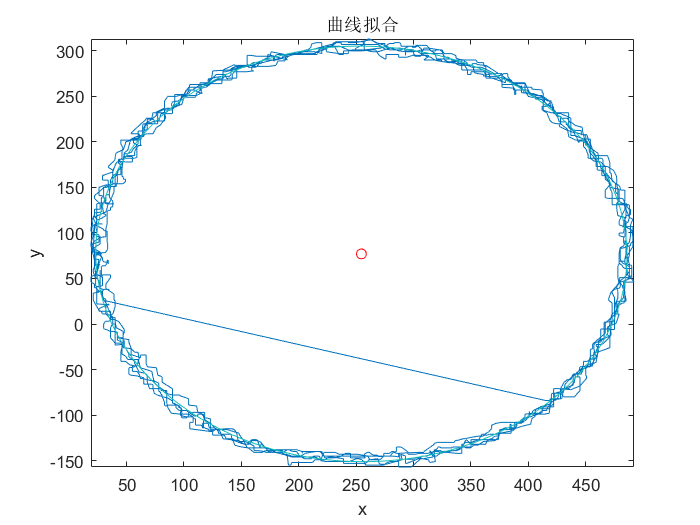

% plot(x(:,1),x(:,2),'ro');


hold on;
plot(X_center,Y_center,'ro');
xmin=min(x(:,1));
xmax=max(x(:,1));
ymin=min(x(:,2));
ymax=max(x(:,2));
% 作图


ezplot(@(x,y)F(p,[x,y]),[xmin,xmax,ymin,ymax]);
title('曲线拟合');

%legend('样本点','拟合曲线')